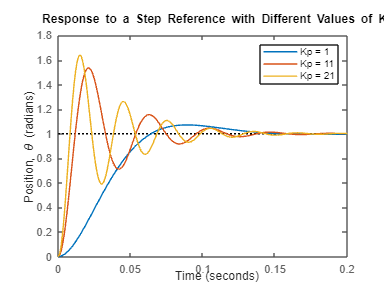

clc;
clear ;
close all;
J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;
s = tf('s');
P_motor = K/(s*((J*s+b)*(L*s+R)+K^2));

Kp = 1;
for i = 1:3
    C(:,:,i) = pid(Kp);
    Kp = Kp + 10;
end
sys_cl = feedback(C*P_motor,1);

t = 0:0.001:0.2;
figure(1);
step(sys_cl(:,:,1), sys_cl(:,:,2), sys_cl(:,:,3), t)
ylabel('Position, \theta (radians)')
title('Response to a Step Reference with Different Values of K_p')
legend('Kp = 1',  'Kp = 11',  'Kp = 21')

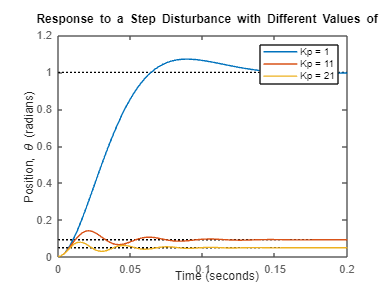


dist_cl = feedback(P_motor,C);
figure(2);
step(dist_cl(:,:,1), dist_cl(:,:,2), dist_cl(:,:,3), t)
ylabel('Position, \theta (radians)')
title('Response to a Step Disturbance with Different Values of K_p')
legend('Kp = 1', 'Kp = 11','Kp = 21')

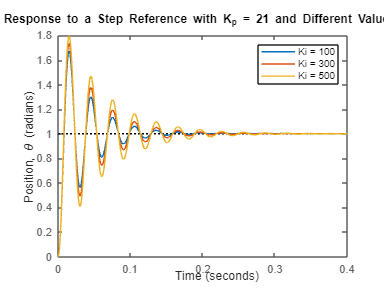


Kp = 21;
Ki = 100;
for i = 1:5
    C(:,:,i) = pid(Kp,Ki);
    Ki = Ki + 200;
end

sys_cl = feedback(C*P_motor,1);
t = 0:0.001:0.4;
figure(2);
step(sys_cl(:,:,1), sys_cl(:,:,2), sys_cl(:,:,3), t)
ylabel('Position, \theta (radians)')
title('Response to a Step Reference with K_p = 21 and Different Values of K_i')
legend('Ki = 100', 'Ki = 300', 'Ki = 500')

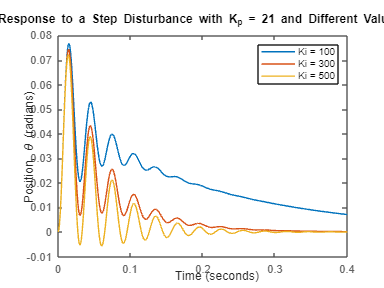


dist_cl = feedback(P_motor,C);
figure(3);
step(dist_cl(:,:,1), dist_cl(:,:,2), dist_cl(:,:,3), t)
ylabel('Position, \theta (radians)')
title('Response to a Step Disturbance with K_p = 21 and Different Values of K_i')
legend('Ki = 100',  'Ki = 300',  'Ki = 500')

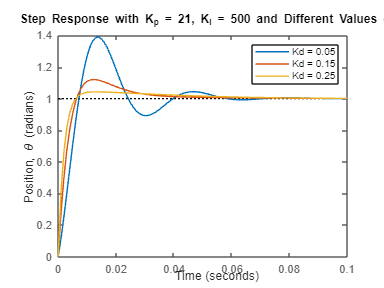


Kp = 21;
Ki = 500;
Kd = 0.05;

for i = 1:3
    C(:,:,i) = pid(Kp,Ki,Kd);
    Kd = Kd + 0.1;
end

sys_cl = feedback(C*P_motor,1);
t = 0:0.001:0.1;
figure(4);
step(sys_cl(:,:,1), sys_cl(:,:,2), sys_cl(:,:,3), t)
ylabel('Position, \theta (radians)')
title('Step Response with K_p = 21, K_i = 500 and Different Values of K_d')
legend('Kd = 0.05', 'Kd = 0.15', 'Kd = 0.25')

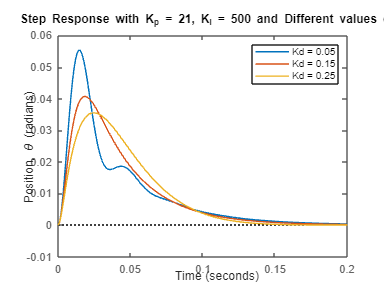


dist_cl = feedback(P_motor,C);
t = 0:0.001:0.2;
figure(5);
step(dist_cl(:,:,1), dist_cl(:,:,2), dist_cl(:,:,3), t)
ylabel('Position, \theta (radians)')
title('Step Response with K_p = 21, K_i = 500 and Different values of K_d')
legend('Kd = 0.05', 'Kd = 0.15', 'Kd = 0.25')


stepinfo(sys_cl(:,:,2))

ans = struct with fields:
         RiseTime: 0.0046
    TransientTime: 0.0338
     SettlingTime: 0.0338
      SettlingMin: 0.9103
      SettlingMax: 1.1212
        Overshoot: 12.1175
       Undershoot: 0
             Peak: 1.1212
         PeakTime: 0.0122
